clear
format shortG
warning off;
load fisheriris
SetRNG(111);

% different datasets to try
inputs_ori = meas(:,1:4);% data 1
inputs = inputs_ori-mean(inputs_ori);


inputs_ori = readtable('nutri.csv');% data 2
inputs_ori = inputs_ori(:,8:end);
inputs_ori = table2array(inputs_ori);
inputs = inputs_ori-mean(inputs_ori);

numPoints = 10000;% data 3
numDimensions = 50;
inputs_ori = 6 * rand(numPoints, numDimensions) - 3;
inputs = inputs_ori-mean(inputs_ori);


% the algorithm to find the acute partition
step = [];
rate = [];
for i = 1:200;
    product = inputs*mean(inputs)';
    signs = sign(product);
    inputs = signs.*inputs;
    rate = [rate;sum(signs == 1)./length(signs)];
    if sum(signs == 1) == length(signs);
        step = [step;i];
    end
end
s = string(step(1));

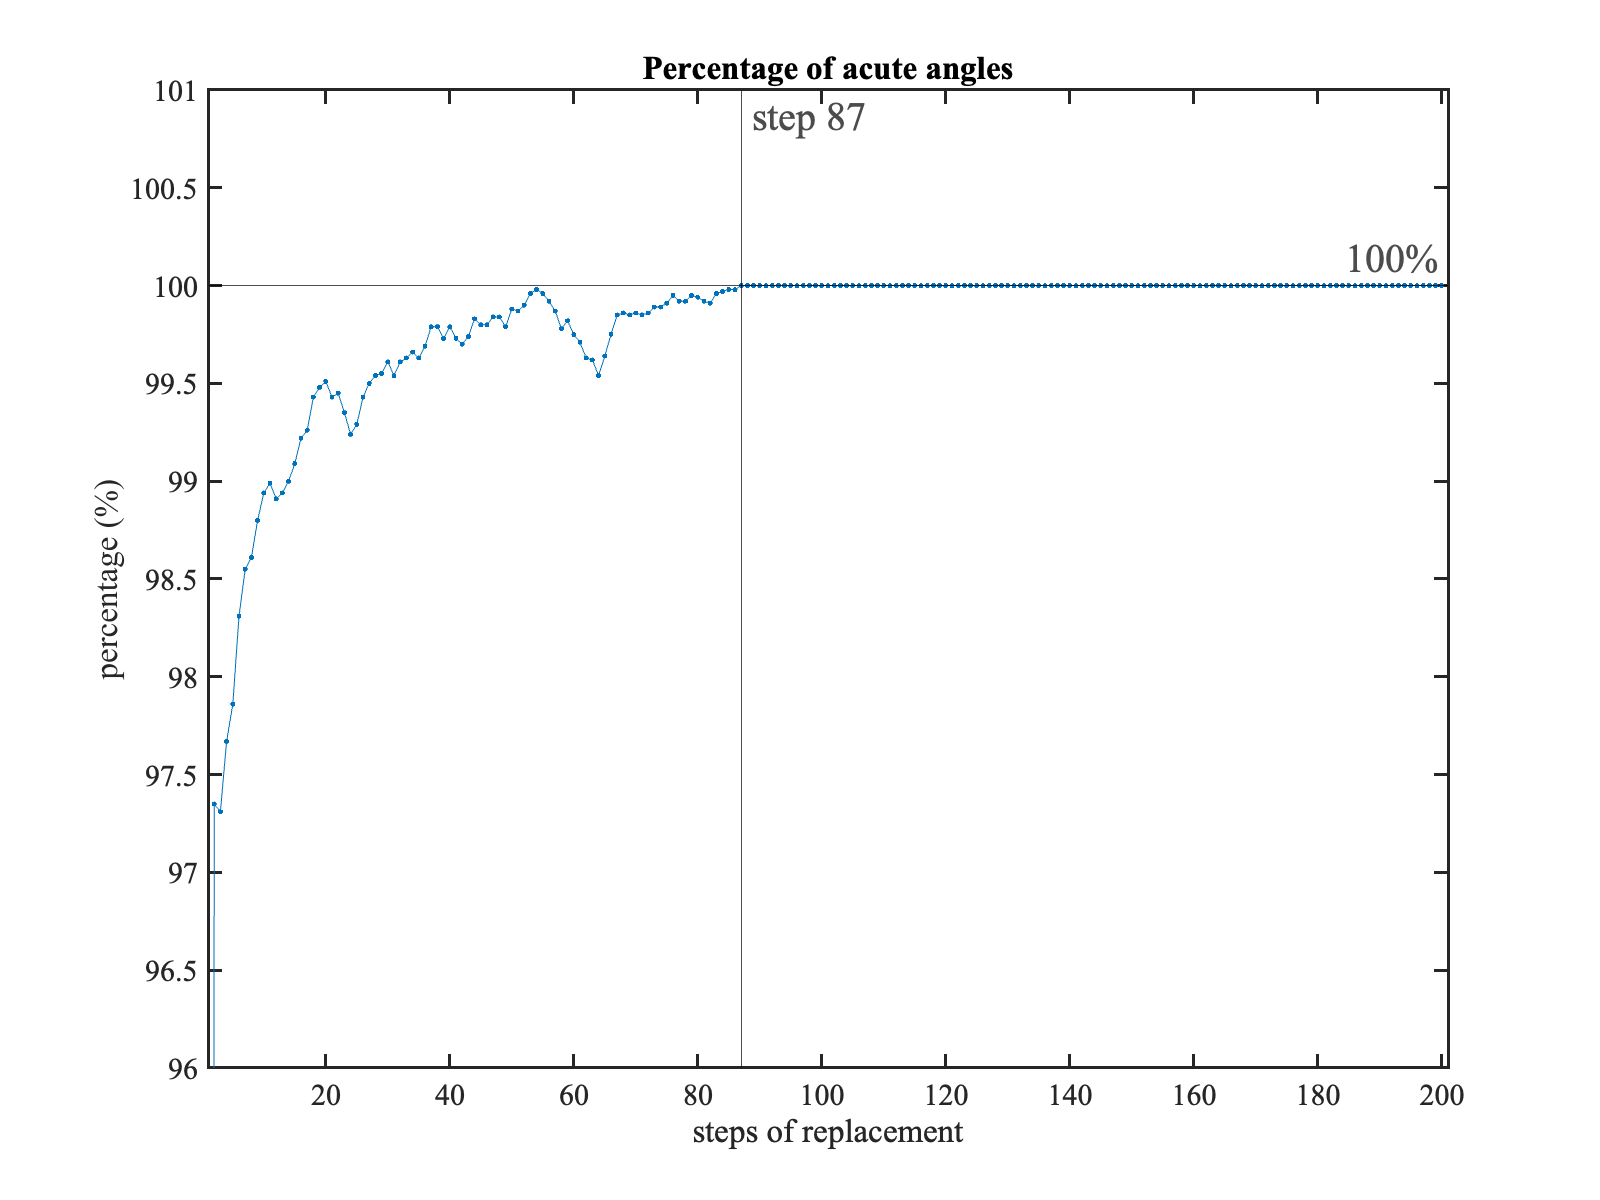

% plot the simulated percentage of acute angles of a partition
rate_percentage = rate * 100;  % Convert to percentage
% Create the plot
figure('Renderer', 'painters', 'Position', [100, 100, 800, 600]); 
plot(rate_percentage, '.-')  % Plot the percentage values
xline(step(1), '-', {['step ', num2str(s)]}, 'FontSize', 20, 'FontName', 'Times New Roman', 'LabelOrientation', 'horizontal', 'Color', 'k');
yline(100, '-', {'100%'}, 'FontSize', 20, 'FontName', 'Times New Roman', 'Color', 'k');
% Adjust y-axis and x-axis limits
ylim([96 101])  % Y-axis from 90% to 100%
xlim([1 201])  % X-axis from 1 to 201

% Add title and labels
title("Percentage of acute angles")
xlabel("steps of replacement")
ylabel("percentage (%)")  % Updated y-axis label to show percentage
set(gca, 'FontSize', 15);% Increase font size
set(gca, 'LineWidth', 1.5); % Make lines thicker
set(gca, 'FontName', 'Times New Roman'); % Set preferred font